Testing whether 

[dt02, mmY] = getDataTable02();


formula = 'zCorr_m1 ~ hemisphere*coLocation*mcPnonc + (1| subjectId)';
mdl2_star = fitlme(dt02,formula);
zErr = zscore(residuals(mdl2_star));
s = abs(zErr) > 2.5;
mdl2 = fitlme(dt02,formula,'Exclude',s);
% mdl2 = fitlme(dt02,formula);
pVals = dataset2table(mdl2.Coefficients(:,'pValue'));
coefficient = dataset2table(mdl2.Coefficients(:,'Name'));
[alphas,h] = holmBonf(0.05,pVals{:,1});
alphas = table(alphas);
mC = [coefficient,pVals,alphas];
mC.Properties.VariableNames = {'coefficient','pVal','corrected_Alpha_Level'};
disp(mC);

               coefficient                  pVal       corrected_Alpha_Level
    _________________________________    __________    _____________________

    {'(Intercept)'                  }       0.20663               0.01      
    {'hemisphere'                   }       0.54072           0.016667      
    {'coLocation'                   }      0.061392          0.0071429      
    {'mcPnonc'                      }       0.73656              0.025      
    {'hemisphere:coLocation'        }       0.27739             0.0125      
    {'hemisphere:mcPnonc'           }       0.12225          0.0083333      
    {'coLocation:mcPnonc'           }       0.99757               0.05      
    {'hemisphere:coLocation:mcPnonc'}    0.00061227            0.00625      




%NOTES: when you use method2 you get nans for values you dont get nans for in method 1, and this
%is in the exact person who has a 'invalid' value for zCorr in method 2 ->
%this is because when you go up to the higher resolution you essentially
%splitting each voxel up into more voxels and then double counting them 

%threshold for standardised residuals(error) of larger or smaller than +-2.5
%remove those points which are outside of that and then run the model again
%justification: spatial correlation - not many independant points in some 



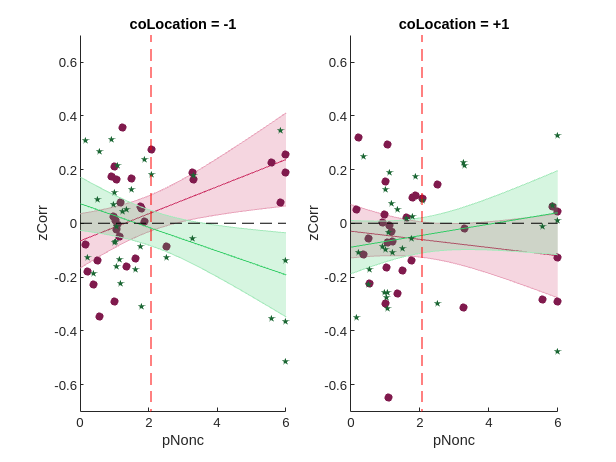


domain.mu = mean(dt02.pNonc);
domain.p = linspace(0,6,144)';
domain.cp = domain.p - domain.mu;

figure;

subplot(121);
hold on;
%%% coloc = -1, left
colocation = -1;
hemisphere = -1;
s = (dt02.coLocation == colocation) & ...
    (dt02.hemisphere == hemisphere);
[X,y,low,upp] = getXEUL(mdl2,...
    1,hemisphere,colocation,domain.cp);
shadedErrorBar(domain.p',y',[upp'-y';y'-low'],...
    'lineprops',{'Color',[0.8,0.2,0.4]});
scatter(dt02.pNonc(s),dt02.zCorr_m1(s),30,...
    [0.5,0.1,0.3],'filled');

%%% coloc = -1, right 
colocation = -1;
hemisphere = +1;
s = (dt02.coLocation == colocation) & ...
    (dt02.hemisphere == hemisphere);
[X,y,low,upp] = getXEUL(mdl2,...
    1,hemisphere,colocation,domain.cp);
shadedErrorBar(domain.p',y',[upp'-y';y'-low'],...
    'lineprops',{'Color',[0.2,0.8,0.4]});
scatter(dt02.pNonc(s),dt02.zCorr_m1(s),30,...
    [0.1,0.4,0.2],'filled','pentagram');

%% Appearence
ylabel('zCorr');
xlabel('pNonc');
ylim([-.7,.7]);
xlim([0,6]);
line([0,6],[0,0],'Color','k','LineStyle','--');
line([domain.mu,domain.mu],[-0.8 0.8],'Color','r','LineStyle','--');
title('coLocation = -1');
hold off;

subplot(122);
hold on;
%%% coloc = +1, left
colocation = +1;
hemisphere = -1;
s = (dt02.coLocation == colocation) & ...
    (dt02.hemisphere == hemisphere);
[~,y,low,upp] = getXEUL(mdl2,...
    1,hemisphere,colocation,domain.cp);
shadedErrorBar(domain.p',y',[upp'-y';y'-low'],...
    'lineprops',{'Color',[0.8,0.2,0.4]});
h1 = scatter(dt02.pNonc(s),dt02.zCorr_m1(s),30,...
    [0.5,0.1,0.3],'filled');

%%% coloc = +1, right 
colocation = +1;
hemisphere = +1;
s = (dt02.coLocation == colocation) & ...
    (dt02.hemisphere == hemisphere);
[~,y,low,upp] = getXEUL(mdl2,...
    1,hemisphere,colocation,domain.cp);
shadedErrorBar(domain.p',y',[upp'-y';y'-low'],...
    'lineprops',{'Color',[0.2,0.8,0.4]});
h2 = scatter(dt02.pNonc(s),dt02.zCorr_m1(s),30,...
    [0.1,0.4,0.2],'filled','pentagram');

%% Appearence
ylabel('zCorr');
xlabel('pNonc');
ylim([-.7,.7]);
xlim([0,6]);
line([0,6],[0,0],'Color','k','LineStyle','--');
h3 = line([domain.mu,domain.mu],[-0.8 0.8],'Color','r','LineStyle','--');
title('coLocation = +1');
hold off;


% lgd = legend([h1,h2,h3],{'left','right','mu pNonc'});
% %lgd.Layout.Tile = 11;
% lgd.Location = 'northeastoutside';
% lgd.ItemTokenSize = [8 6];